syms r w % w is angular speed
v = w * r

$$v = r\,w$$

x = @(t) v * t

x = function_handle with value:
    @(t)v*t


y = @(t) r

y = function_handle with value:
    @(t)r



% assume at t = 0, disk center o is at (0, r)
% and point p is at (a, r)
% at any time t, we have p's location relative to o
% is [o(t).x + cos(w * t) * a, o(t).y + sin(w * t) * a]
syms a
p = @(t) [x(t) + cos(-w * t) * a; y(t) + sin(-w * t) * a]

p = function_handle with value:
    @(t)[x(t)+cos(-w*t)*a;y(t)+sin(-w*t)*a]



fp = matlabFunction(subs(p, {r, a, w}, {1.0, 0.3, 1.0}))

fp = function_handle with value:
    @(t)[t+cos(t).*(3.0./1.0e1);sin(t).*(-3.0./1.0e1)+1.0]


pts = fp(linspace(0, 20, 500))

pts =     0.3000    0.3398    0.3792    0.4181    0.4565    0.4944    0.5318    0.5688    0.6054    0.6414    0.6770    0.7122    0.7469    0.7812    0.8151    0.8486    0.8817    0.9144    0.9467    0.9787    1.0103    1.0415    1.0725    1.1031    1.1335    1.1636    1.1934    1.2230    1.2523    1.2815    1.3104    1.3392    1.3678    1.3963    1.4247    1.4530    1.4812    1.5093    1.5374    1.5654    1.5935    1.6216    1.6497    1.6778    1.7061    1.7344    1.7628    1.7914    1.8201    1.8490
    1.0000    0.9880    0.9760    0.9640    0.9521    0.9403    0.9285    0.9169    0.9054    0.8941    0.8830    0.8720    0.8612    0.8507    0.8404    0.8303    0.8205    0.8110    0.8019    0.7930    0.7845    0.7763    0.7684    0.7610    0.7539    0.7472    0.7410    0.7351    0.7297    0.7247    0.7201    0.7160    0.7124    0.7092    0.7065    0.7042    0.7025    0.7012    0.7003    0.7000    0.7002    0.7008    0.7019    0.7035    0.7056    0.7081    0.7111    0.7146    0.7185   

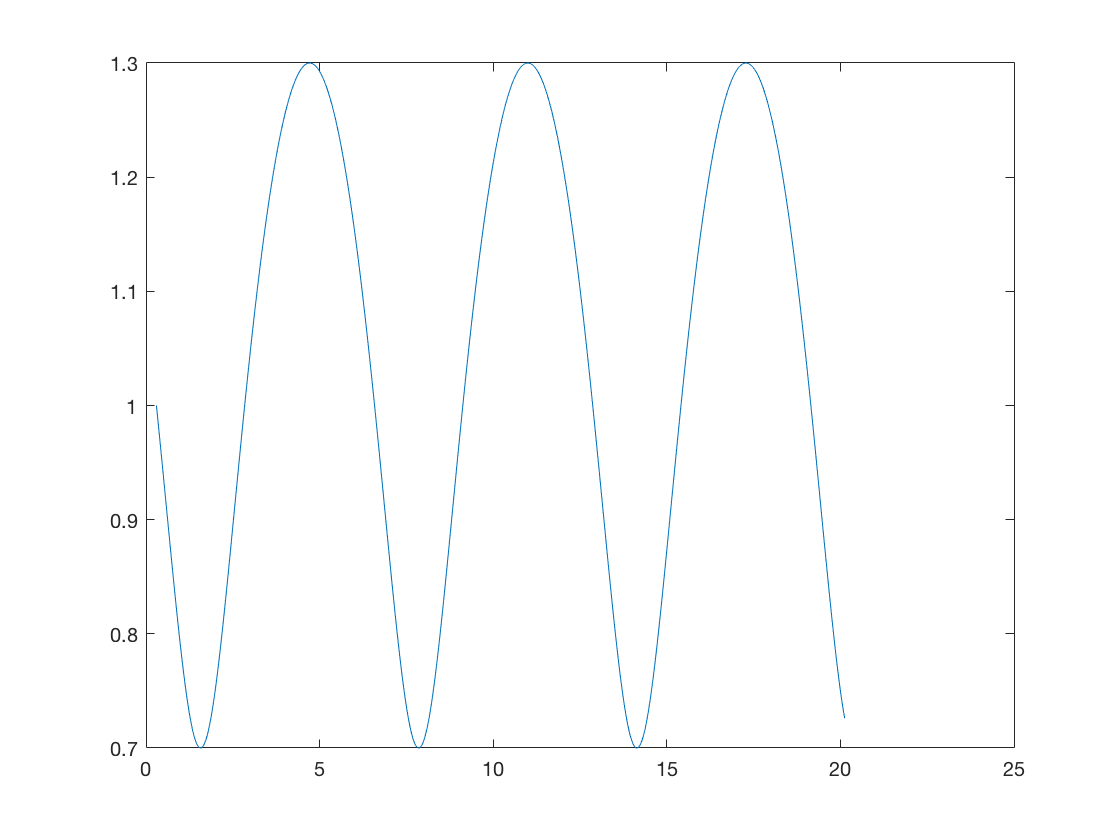

plot(pts(1,:), pts(2,:))